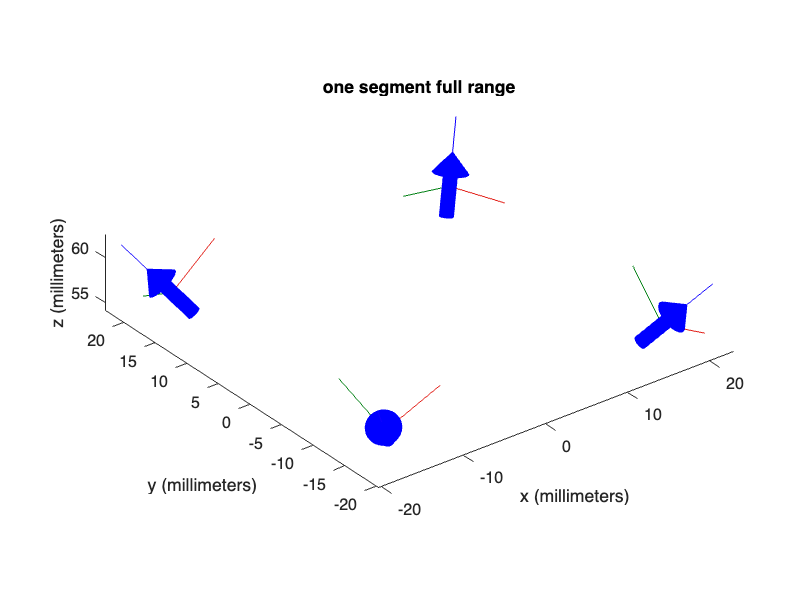

l = 16*4; % mm
phi = [pi/4 3*pi/4 5*pi/4 7*pi/4];
kappa = pi./(l*4);

T = zeros(4,4);

% generate transforms for each point
for i = 1:length(phi)
    for j = 1:length(kappa)
            T(:,:,(i-1)*length(kappa)+j) = generate_transformation_matrix(l, phi(i), kappa(j));
    end
end


% plot each transform
for k = 1:length(phi)*length(kappa)
    plotTransforms(T(1:3,4,k)', rotm2quat(T(1:3,1:3,k)), FrameSize=7, MeshFilePath="arrow_z.STL", MeshColor="b")
    hold on
end

title("one segment full range")
xlabel("x (millimeters)")
ylabel("y (millimeters)")
zlabel("z (millimeters)")
axis equal
hold off

function pwm_cmds = dl_2_pwm(dl, disc_diameter, pwm_range, zero_point)
    dtheta = 2 * dl / (disc_diameter);
    dpwm = dtheta * pwm_range / pi;
    pwm_cmds = ones(size(dpwm)) * zero_point + dpwm;
end

function dl = inverse_kinematics(x,y,l_0,d)
    
    options = optimoptions('fmincon','Display','notify');
    
    dl = fmincon(@min_func, [-.001,-.01,-.001,-.001], [1 1 1 1], [0], [], [], [], [], @(dl) cc_constraint(dl, x, y, l_0, d), options);

end

function [l_1, l_2, l_3, l_4] = delta_2_length(l_0, dl_1, dl_2, dl_3, dl_4)
    if nargin == 2
        dl_2 = dl_1(2);
        dl_3 = dl_1(3);
        dl_4 = dl_1(4);
        dl_1 = dl_1(1);
    end
    l_1 = l_0 + dl_1;
    l_2 = l_0 + dl_2;
    l_3 = l_0 + dl_3;
    l_4 = l_0 + dl_4;
end

function [l, phi, kappa] = robot_specific_transformation(d, l_1, l_2, l_3, l_4)
    l = (l_1 + l_2 + l_3 + l_4)/4;

    kappa_x = (l_3-l_1)/(d*(l_1+l_3));
    kappa_y = (l_4-l_2)/(d*(l_2+l_4));

    kappa = sqrt(kappa_x^2 + kappa_y^2);

    phi = atan2(kappa_y, kappa_x);
end

function T = generate_transformation_matrix(l, phi, kappa)
    dh_matrix = [  phi    ,                      0, 0, -pi/2; 
                 kappa*l/2,                      0, 0,  pi/2; 
                         0, 2/kappa*sin(kappa*l/2), 0, -pi/2; 
                 kappa*l/2,                      0, 0,  pi/2; 
                      -phi,                      0, 0,     0];
    if kappa == 0
        dh_matrix(3,2) = l;
    end

    T = eye(4);

    for i=1:size(dh_matrix,1)
        %disp(T)
        T = T*generate_dh(dh_matrix(i,:));
    end
    %disp(T)
end

function T = generate_dh(dh_params)
    theta = dh_params(1);
    d     = dh_params(2);
    r     = dh_params(3);
    alpha = dh_params(4);

    Z = [cos(theta), -sin(theta), 0, 0;
         sin(theta),  cos(theta), 0, 0;
                  0,           0, 1, d;
                  0,           0, 0, 1];

    X = [1,          0,           0, r;
         0, cos(alpha), -sin(alpha), 0;
         0, sin(alpha),  cos(alpha), 0;
         0,          0,           0, 1];

    T = Z*X;
end

function [c,ceq] = cc_constraint(dl, x, y, l_0, d)
    phi = atan2(y,x);
    a = sqrt(x^2+y^2);
    [l_1, l_2, l_3, l_4] = delta_2_length(l_0, dl);
    [l_out, phi_out, kappa_out] = robot_specific_transformation(d, l_1, l_2, l_3, l_4);
    c = [];
    if kappa_out == 0
        ceq = [phi - phi_out; -a];
    else
        ceq = [phi - phi_out; (1-cos(l_out*kappa_out))/kappa_out - a];
    end
end

function y = min_func(dl)
    y = sum(abs(dl));
end

function [T_ext_Z] = extend_transfromation_z(T, L_ext)
    z = T(3, 1:3); % pick out z direction
    o_original = T(1:3, 4);
    o_new = o_original' + L_ext * (z .* [-1 -1 1]); % why do i need flip the signs of x and y here?
    T_ext_Z = T;
    T_ext_Z(1:3,4) = o_new';
end